clear all
private_addpath('Advanpix/');

dim = 200;
domain = mp('[-pi pi;-4*pi 4*pi]');

sysinfo = SystemInfo(dim, domain);
qstate = FundamentalState(sysinfo, 'q');
pstate = FundamentalState(sysinfo, 'p');

qcs = qstate.coherent(0, 0);
pcs = pstate.coherent(0, 0);
hbar = qcs.hbar;

x = qcs.x;
y = qcs.y;

dx = sum(x .^2 .* y)


dx = 

    0.7943413745700856192110400893322578



x = pcs.x;
y = pcs.y;
dy = sum(x .^2 .* y)


dy = 

    -5.414866210903796623532496706634653e-16 -     1.641176669496434869310070420619277e-36i



disp("-------------")

-------------


qcs.hbar/2


ans = 

    0.06283185307179586476925286766559006



sqrt(dx*dy)


ans = 

    3.142932584639815114860050309754419e-29 -     2.07394606224039321049700582049023e-08i




fig = figure(1);
ax1 = subplot(2,2,1);
ax2 = subplot(2,2,2);
ax3 = subplot(2,2,3);
ax4 = subplot(2,2,4);
hold on

[x,y,z] = qcs.hsmrep('ismp',false);

periodic = logical
   0


contour(ax1, x, y, log10(z), 10 , 'LineColor', 'none', 'Fill','on');

[x,y,z] = pcs.hsmrep('ismp',false);

periodic = logical
   0


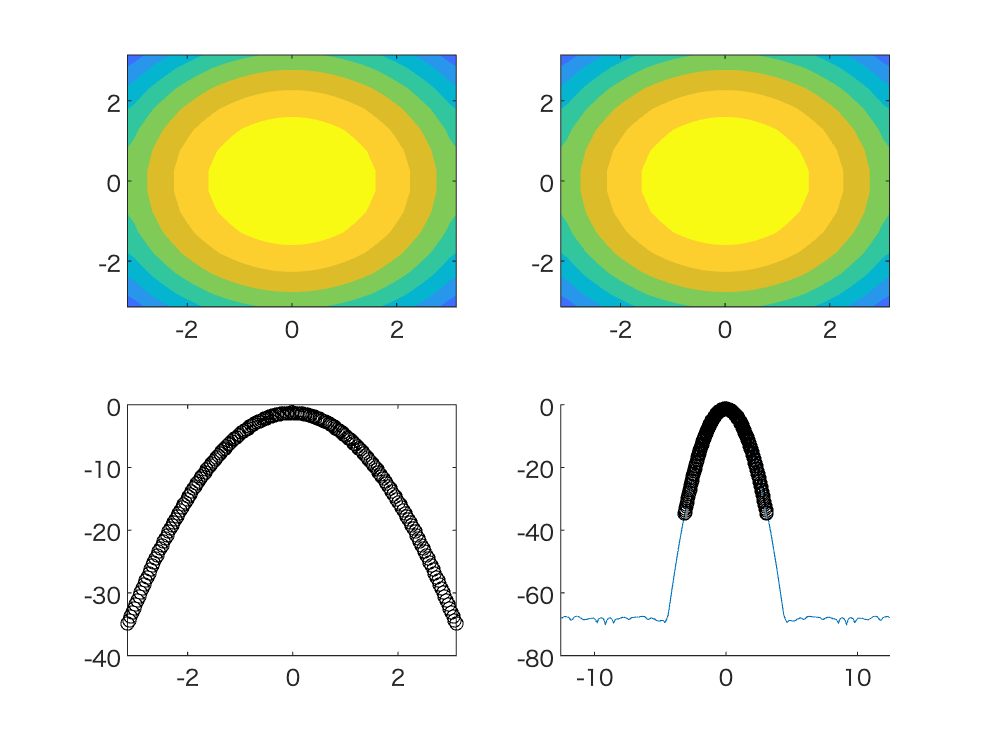

contour(ax2, x, y, log10(z), 10 , 'LineColor', 'none', 'Fill','on');
axis(ax1, [-pi pi -pi pi])
axis(ax2, [-pi pi -pi pi])

plot(ax3, pcs.x, log10(pcs.abs2()))
plot(ax3, qcs.x, log10(qcs.abs2()), 'ok')

pvec = qcs.q2p();
qvec = pcs.p2q();

plot(ax4, pvec.x, log10(pvec.abs2()))
plot(ax4, qvec.x, log10(qvec.abs2()), 'ok')


hold off

function y = cs(x, hbar, qc, pc)
  arguments
      x {mustBeNumeric};      
      hbar {mustBeReal};
      qc {mustBeReal};
      pc {mustBeReal};
  end
  if isrow(x)
      x = x.';
  end  
  y = exp( -(x - qc) .^ 2 /hbar + 1j*(x - qc) * pc / (2*hbar) );
end